# Replicating Strategy - Question 1b

Given values

S0 = 72.99;         % Closing price
mu = 11.75/100;     % Annualized return
sigma = 24.98/100;  % Annualized Volatility
rho = 1/100;        % Annualized interest rate
K = 80;             % Strike price
T = 42;             % Period - 2 months (21 days per month)

## Creating the plot

N = 50;

delta_array = zeros([1, N]);
for n=1:N
    delta_array(n) = Q1a(mu, sigma, rho, S0, K, T, n);
end

delta_array

delta_array = 	1.0e+-14 *

         0         0    0.0152    0.0409    0.0314    0.0599    0.0312    0.0615    0.0057    0.0253    0.0276    0.0594    0.1111    0.0421    0.0977    0.0467    0.0781    0.0102    0.0212    0.0878    0.0341    0.0235    0.0363    0.0871    0.0128         0    0.0807    0.2064    0.0141    0.2589    0.2350    0.0150    0.0153         0    0.3009         0         0    0.3664    0.0338    0.3951    0.0349    0.0177    0.0538    0.0546    0.4423    0.0187    0.4538    0.0383    0.0387    0.4900


Compute the call option

d1 = (log(S0/K) + rho*T)/(sigma*sqrt(T)) + 1/2*sigma*sqrt(T);
c = S0 * normpdf(d1) - K * exp(-rho*T) * normpdf(d1 - sigma*sqrt(T) )

c = 7.1054e-15

c_upper = 0.98 * c;
c_lower = 1.02 * c;

The plot

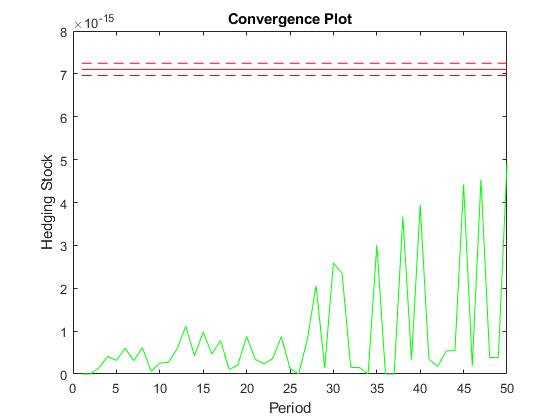

figure(1)
plot(1:N, delta_array, '-g', [1, N], [c, c], '-r', [1, N], [c_lower, c_lower], '--r', [1, N], [c_upper, c_upper], '--r')
title('Convergence Plot')
xlabel('Period')
ylabel('Hedging Stock')